Defining necessary variables and opening our group folder

% ok lets gooooooooooooo!!!!!
% testim = imread("CV_zebracrossing_images/pic1.jpg");
% imshow(testim)

%Opening folder
Imfolder = 'CV_zebracrossing_images';
if ~isfolder(Imfolder)
  errorMessage = sprintf('Error: The following folder does not exist:\n%s', Imfolder);
  uiwait(warndlg(errorMessage));
  return;  
end

% Get a list of all image files in the folder
imageFiles = dir(fullfile(Imfolder, '*.jpg')); 

%Variable declaration
imnum = numel(imageFiles);
stockImages = cell(1, imnum);
images = cell(1, imnum);
imheight = zeros(1, imnum);
imcropped = cell(1, imnum);
imgray = cell(1,imnum);
binim = cell(1,imnum);
gaussianFilter = fspecial('gaussian', [5 5], 2);
imfiltered = cell(1,imnum);
edgedetected = cell(1,imnum);
edgedetectClean = cell(1,imnum);
angle = cell(1,imnum);
lineLength = cell(1,imnum);
zebra_Stripes = cell(1,imnum);
imageOverlay = cell(1,imnum);
detectedCrossing = zeros(1,imnum);

imnum = 50

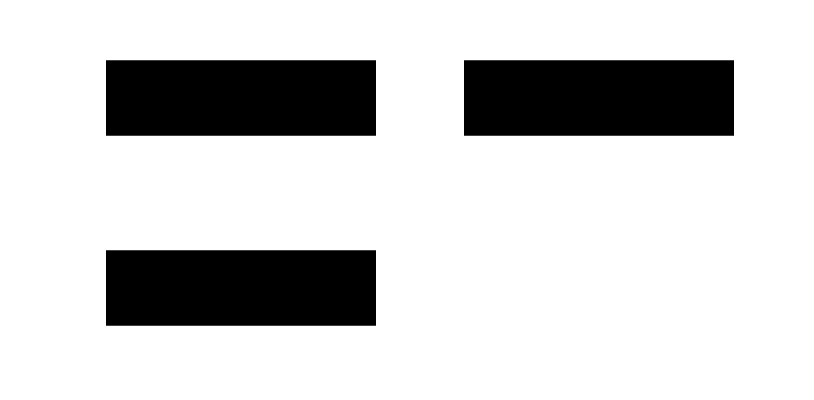

durchschnitt = 61.9604

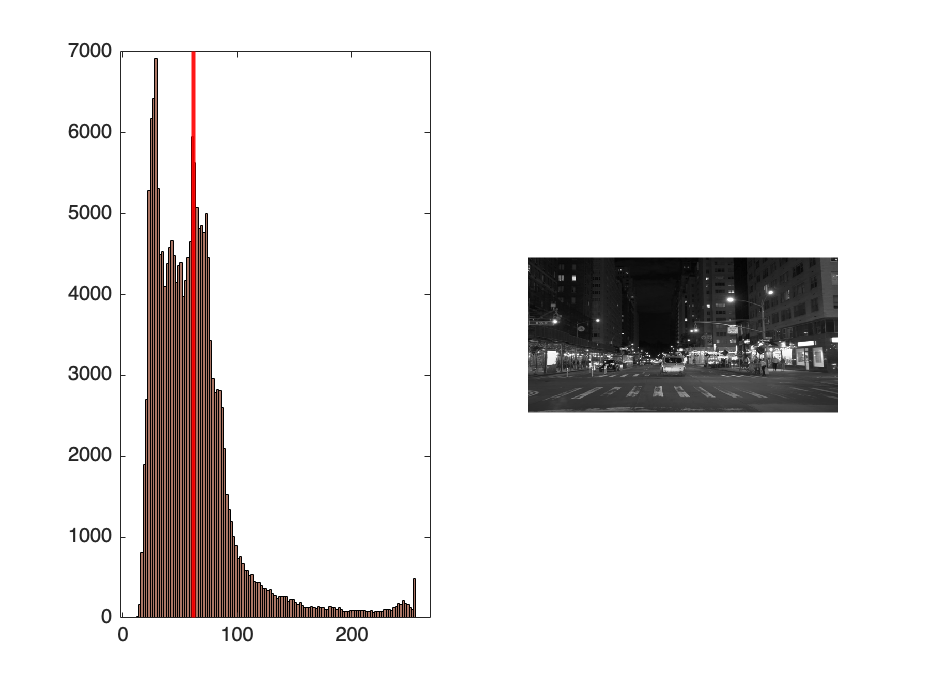

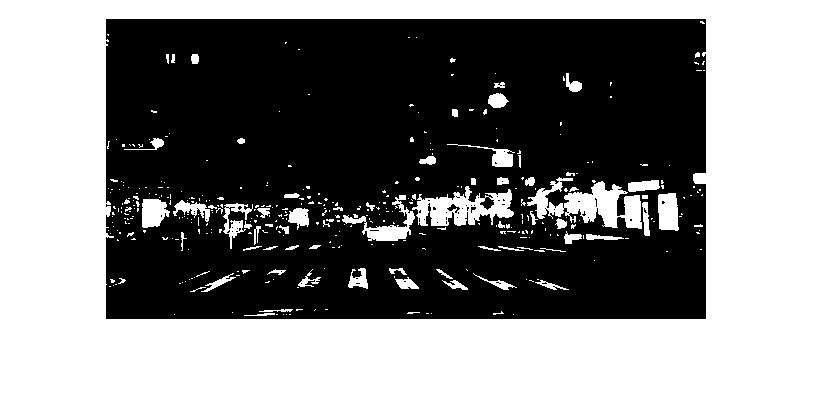

for idx = 1:imnum
    %read all images
    filename = fullfile(Imfolder, imageFiles(idx).name);
    stockImages{idx} = imread(filename);
    %resize all images to one size for optimal cropping
    images{idx}=imresize(stockImages{idx},[300,600]);
    imcropped{idx} = imcrop(images{idx}, [0.5 133 600 167])
    %create a grayscale image 
    imgray{idx} = im2gray(imcropped{idx});
    medgray(idx) = mean(imfiltered{idx}(:));
    imfiltered{idx} = imfilter(imgray{idx}, gaussianFilter, 'conv', 'replicate');
    binim{idx} = imfiltered{idx} > k_threshold(idx); 

    edgedetected{idx} = edge(imgray{idx}, 'canny');
 
    edgedetectClean{idx} = bwareaopen(edgedetected{idx}, 50);
    %Ab hier für alle bilder den neuen Code
    morphedLines = bwmorph(edgedetected{idx}, 'bridge');

    [B, L, N] = bwboundaries(edgedetected{idx});
    RGB = label2rgb(L);

    binaryImage = RGB(:,:,1) > 253; % Adjust someThreshold as needed

    OriginalImg = binaryImage;
    SwitchedImage = ~binaryImage;

    numOnes = sum(~binaryImage(:) == 1);
    totalElements = numel(~binaryImage);
    percentageOnes = (numOnes / totalElements) * 100;

    if percentageOnes > 10
        detectedCrossing(idx) = 1;
    else 
        detectedCrossing(idx) = 0;
    end
    
    SE = strel("disk",5);
   
    BW1 = imerode(SwitchedImage,SE);
    BW1_rgb_1 = repmat(BW1, [1 1 3]);
    BW1_double = double(BW1_rgb_1);

    imageOverlay{idx} = imcropped{idx} + uint8(BW1_double) .* 255;
    

end
    
    for j = 1:imnum
            figure(1);
            subplot(7, 8, j);
            imshow(imageOverlay{j});
            if detectedCrossing(j) == 1
                title("Zebra Crossing 1");
            else
                title("No Zebra Crossing 0");
            end
    end